# Physical Model of Tenor Ukulele

### Physical Models for Sound Synthesis 

#### Simon Rostami Mosen, 20176458

## Introduction

The ukulele is Hawaiian string instrument in the family of guitar instruments [2]. It consists of four strings and comes in three different sizes: Soprano, Tenor, Concert and Baritone and shares a selection of attributes with the acoustic guitar such as consisting of a fret board, frets, sound hole and tail piece [2]. This project aims to model a Tenor ukulele based on Partial Differential Equations and Finite Difference Methods. 

Before introducing code, below is a walkthrough of the theory behind modeling a Ukulele string. 

## String Models 

The 1D-wave equation can be considered the basis for modeling a string [1]:


$$u_{tt} = \gamma^2u_{xx}$$


While the wave equation only describes an ideal string with a perfectly harmonic spectrum, it is worth looking at the equation for the Ideal Bar. 


$$    u_{tt} = -k^2u_{xxxx}
$$


The equations for an Ideal Bar can be used together with the 1D wave equation to introduce stiffness, the material's resistance to deformation, to the model [1]. The combined equation, namely the equation for a Stiff String, is seen below: 


$$u_{tt} = \gamma^2u_{xx}-\kappa^2u_{xxxx}
$$


As the vibrations of a real string decay over time, *loss *or *damping* is introduced to the model [1]:


$$u_{tt} = \gamma^2u_{xx}-\kappa^2u_{xxxx}-2\sigma_0u_{t+2}\sigma_1u_{txx}
$$


In the real world, frequencies do not decay at the same rate, why this model introduces both frequency-independent and frequency-dependent damping. 

## Discretisation

As these models operate in continuous time there is need for discretisation! 

The following operators are used to approximate discrete time.

First-order time difference operator:


$$u_{t} \approx\left\{\begin{array}{ll}
\delta_{t+} u_{l}^{n}=\frac{1}{k}\left(u_{l}^{n+1}-u_{l}^{n}\right) & \text { Forw. time diff. } \\
\delta_{t-} u_{l}^{n}=\frac{1}{k}\left(u_{l}^{n}-u_{l}^{n-1}\right) & \text { Backw. time diff. } \\
\delta_{t} \cdot u_{l}^{n}=\frac{1}{2 k}\left(u_{l}^{n+1}-u_{l}^{n-1}\right) & \text { Cent. time diff. }
\end{array}\right.$$
 

First-order space difference operator:


$$u_{x} \approx\left\{\begin{array}{ll}
\delta_{x+} u_{l}^{n}=\frac{1}{h}\left(u_{l+1}^{n}-u_{l}^{n}\right) & \text { Forw. space diff. } \\
\delta_{x-} u_{l}^{n}=\frac{1}{h}\left(u_{l}^{n}-u_{l-1}^{n}\right) & \text { Backw. space diff. } \\
\delta_{x} \cdot u_{l}^{n}=\frac{1}{2 h}\left(u_{l+1}^{n}-u_{l-1}^{n}\right) & \text { Cent. space diff. }
\end{array}\right.$$


Second-order time difference operator:


$$u_{t t} \approx \delta_{t t} u_{l}^{n}=\delta_{t+} \delta_{t-} u_{l}^{n}=\frac{1}{k^{2}}\left(u_{l}^{n+1}-2 u_{l}^{n}+u_{l}^{n-1}\right)
$$


Second-order space difference operator:

 
$$u_{x x} \approx \delta_{x x} u_{l}^{n}=\delta_{x+} \delta_{x-} u_{l}^{n}=\frac{1}{h^{2}}\left(u_{l+1}^{n}-2 u_{l}^{n}+u_{l-1}^{n}\right)
$$


This is the very foundation of modeling of a string. The remaining equations and theory will be covered while going through the implementation below,

## Implementation

The code below is only used to call the `ukuleleString.m `function. It strums over all four strings. This is not interesting for now. 

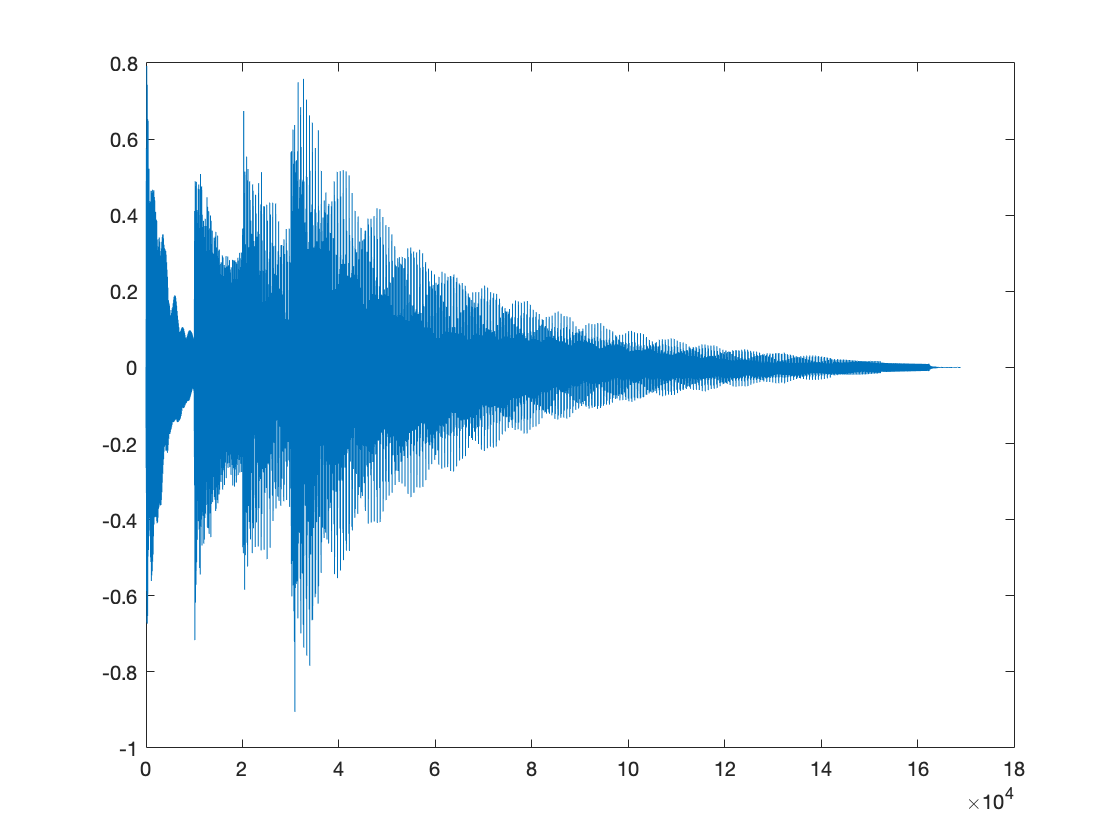


clear all; close all; clc;
[out, fs] = ukuleleString(440, 0.7, 0.02);
[out1, fs] = ukuleleString(329.63, 0.7, 0.02);
[out2, fs] = ukuleleString(261.63, 0.7, 0.02);
[out3, fs] = ukuleleString(392, 0.7, 0.02);

gap = zeros(10000,1);

out =[out; gap; gap; gap;];
out1 = [gap; out1; gap; gap;];
out2 = [gap; gap; out2; gap;];
out3 = [gap; gap; gap; out3];

A = (out+out1+out2+out3)*0.4;
plot(A)


%audiowrite('ukuleleTest.wav',A,fs);
soundsc(A,fs)

## The `ukuleleString` function

To synthesize a ukulele string, the following function was created. 

The functions takes 3 arguments, freq, s0Damp and s1Damp, being the fundamental frequency of the string, the frequency independent damping coefficient, as well as the frequency dependent damping coefficient.

function [out, fs] = ukuleleString(freq, s0Damp, s1Damp)


An impulse response of a Kala Triback Ukulele (see picture below) was read for later use. 

 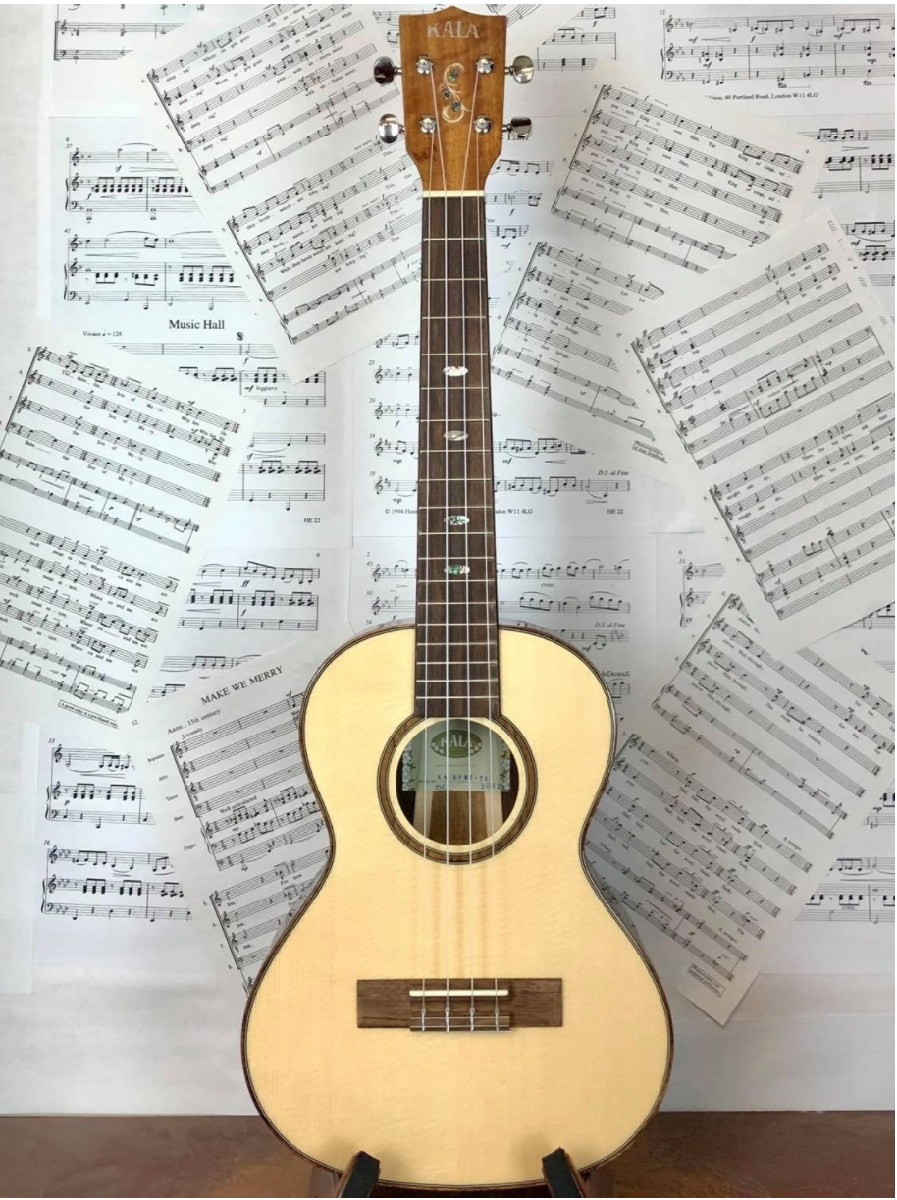

[y, fs] = audioread('Kal Triback 3c.wav'); 
% reference: https://www.3sigmaaudio.com/items/category/ukuleles/ 


A time-domain and frequency domain plot of the impulse response is seen below:

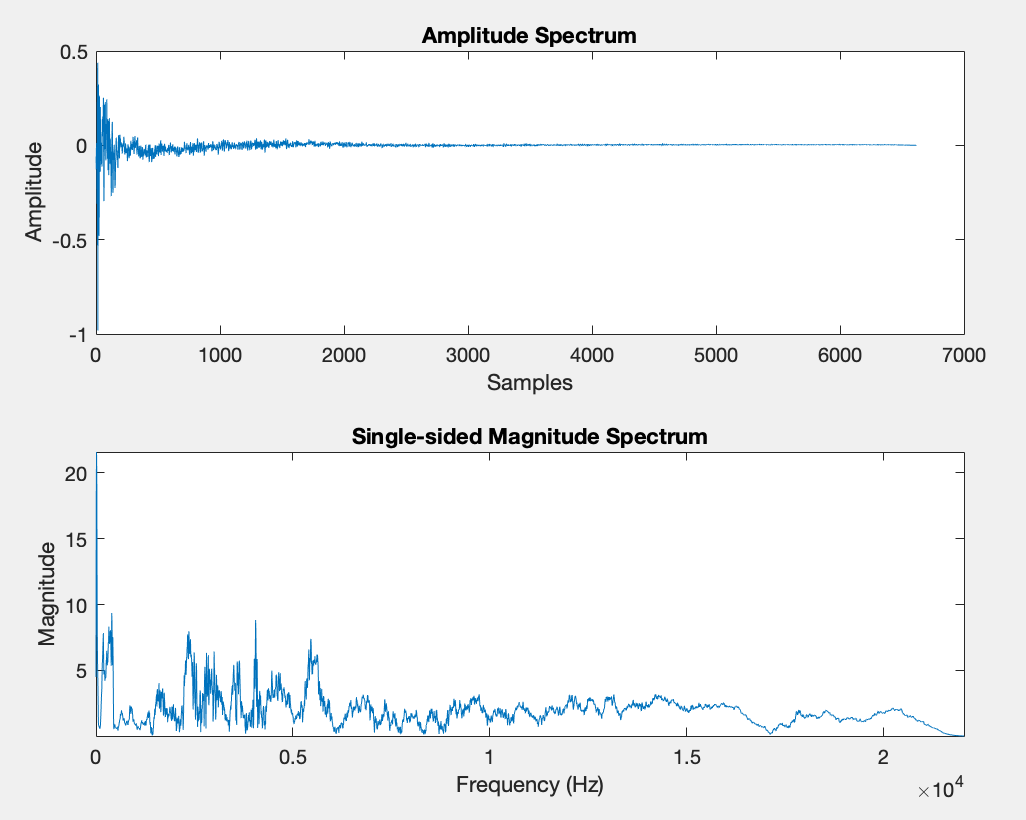


fs = 44100;               % sample rate
k = 1 / fs;               % time step
duration = fs * 3;        % duration
f0 = freq;
excitationWidth = 1;    %width of excitation


The length of the strings were based on a Tenor ukulele, and set to 66 cm. 

L = 0.66; % 
% reference: https://www.masterclass.com/articles/a-guide-to-ukulele-strings#how-many-strings-does-a-ukulele-have

c = 2*L*f0;


As only ideal strings are entirely harmonic, it is worth defining the inharmonicity coefficient B [1]:


$$B=\frac{\pi \;Q\;A\;K^2 }{T\;L^2 }\;$$


where Q is Young's Modulus, A is the cross-sectional area of the string and L is the length of the string, $K^2$ is the Radius of Gyration, T is the tension of the string and L is the length of the string. 

To accurately model a ukulele string, the inharmonicity coefficient was found in [2]. To implement this, the R was isolated from the equation below. This was possible as:


$$K^2 =\frac{I}{A}$$


where I is the Moment of Inertia and A is the cross-sectional area of the string.

The Moment of Inertia, furthermore, given by:

$I=\pi \;\frac{R^4 }{4}$ .

By substituting the definitions of the Radius of Gyration and Moment of Inertia into the equation for B, it now looks as follows: 


$$B=\frac{\pi^3 \;Q\;R^4 }{4\;T\;L^2 }$$


By isolating R, the following equation is found:


$$R=\frac{4^{0\ldotp 25} \;B^{0\ldotp 25} \;C^{0\ldotp 25} \;L^{0\ldotp 5} }{\pi^{0\ldotp 25} \;Q^{0\ldotp 25} }$$



Q = 4.905e+9; % Young's Modulus of nylon in Pa from [2]. 

B = 2.50e-04; % Inharmonicity coefficient from [2].

R = (4^(1/4)*B^(1/4)*c^(1/4)*L^(1/2))/(pi^(1/4)*Q^(1/4));

I = pi/4 * R^4; % Moment of Inertia

A = pi*R^2; % Cross-sectional area of string

p = 1.15e3; % Denisity, kg/m3. 
% Reference: https://www.engineeringtoolbox.com/engineering-materials-properties-d_1225.html

K = (Q * I)/(p*A); %Stiffness parameter

The damping coefficients are assigned to the function arguments, and the grid spacing and courant number is calculated based on the variables.


s0 = s0Damp;
s1 = s1Damp;

% Calculate grid spacing from variables
h = sqrt((c^2*k^2 + 4*s1*k + sqrt((c^2*k^2 + 4*s1*k)^2 + 16*K^2*k^2))/2);
N = floor(L/h);
h = L / N;

% Calculate courant numbers
lambda = c * k / h;
mu = (K * k) / h^2;


To excite the strings, a triangle window is used to imitate a plucking action of the string. 

% Excitation using triangle window
u = zeros(N+1,1);
u(3:9) = triang(excitationWidth);

% Grid functions
uPrev = u;
uNext = zeros(N,1); 

% Initialise output and output position
out = zeros(duration, 1);
outPos = floor(N / 2);

The discretized version of the stiff string is implemented below. A clamped boundary condition is used, where the first two indicies as well as the two last indicies are set to 0.


for n = 1:duration
    % update equation
    
    for l = 3:N-2 % clamped boundary condition
        stiffness = mu^2 * (u(l+2)-4*u(l+1)+6*u(l)-4*u(l-1)+u(l-2));
        freqIndependentDamping = s0 * k * uPrev(l);
        freqDependentDamping = ((2*s1*k)/(h*h)) * (u(l+1) - 2*u(l) + u(l-1) - ...
           uPrev(l+1) + 2*uPrev(l) - uPrev(l-1));
        uNext(l) = 1/(1+s0*k) * ((2 * u(l) - uPrev(l) + lambda^2 * (u(l-1) - ...
            2 * u(l) + u(l+1))) - stiffness + freqIndependentDamping+freqDependentDamping);
    end
    
    % output
    out(n) = uNext(outPos);
    
    

Variables are iterated in the end of the for-loop. 

    uPrev = u;
    u = uNext;
   
end

As this model, so far, has only focused on modeling the string itself, this does not fully represent the real ukulele, where the body of the instrument resonates when the strings are excited. 

To capture the sound of the body, an impulse response was acquired from https://www.3sigmaaudio.com/items/category/ukuleles/ and applied to our dry string signal using convolution.

Convolution is given by the following equation [3]:


$$y[n]=x[n] * h[n]=\sum_{m=1}^{M} x[n-m+1] \cdot h[m]$$


Where  y[n] is the output signal, x[n] is the input signal, h[n] is the impulse response.


out = conv(out,y); 
end


Spectrograms of the output before and after convolution with the impulse response is seen below:

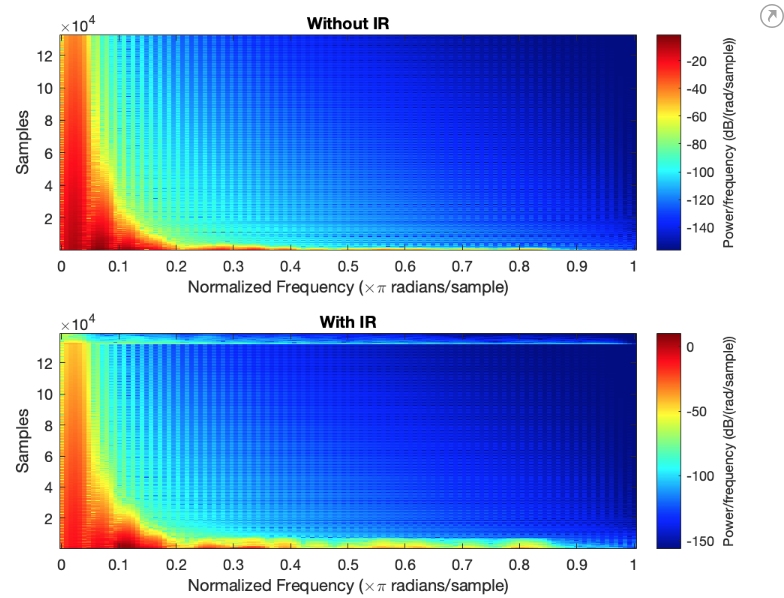

It is seen that, with the impulse response, the sound features a more complex spectrum across the higher frequencies, compared to the output without the impulse response. 

References:

[1] Bilbao, Stefan. *Numerical sound synthesis: finite difference schemes and simulation in musical acoustics*. John Wiley & Sons, 2009.

[2] SOON, KIRSTEN WONG PIK. *Analysis of Ukulele Tones with Comparisons to the Pipa and Classical Guitar*. Diss. National University of Singapore, 2014.

[3] Tarr, Eric. *Hack Audio: An Introduction to Computer Programming and Digital Signal Processing in MATLAB*. Routledge, 2018.